# Multi Mass-Spring System

## Problem Statement

Solve for the EOMs of a 3-mass, 4-spring system.

Determine the modes of vibration for the system.

Assume equal masses, m, and spring constants, k.

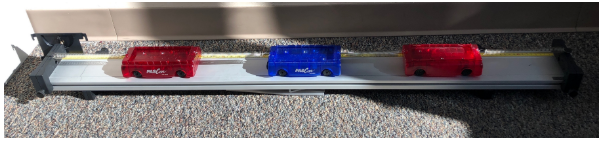

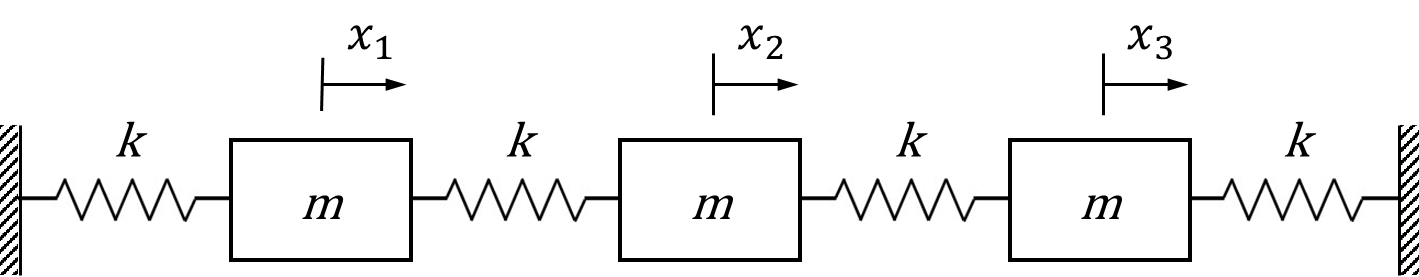

## Step 1: Conceptualize the Problem

Linear, massless, springs

No damping

3 DOF $x_1, x_2, x_3 \rightarrow$3 EOMs $\ddot{x}_1,\ddot{x}_2,\ddot{x}_3$

## Step 2: Coordinate System

Cartesian system with x horizontal and y vertical.

## 

## Step 3: FBD

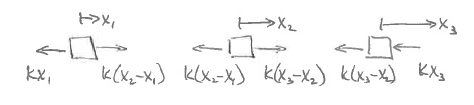

Note that the FBD is drawn with $x_3>x_2>x_1$. This is not a restriction, it just allows us to get the signs of the spring forces correct.

m: mass

k: spring constant

$x_i, i=1,2,3$: linear displacement of each mass in the x-direction

## Step 4: Fundamental Equations

clear variables
clc
syms m k x1 x2 x3 x1ddot x2ddot x3ddot


$$\sum F_{x_1} = m\ddot{x}_1 = -kx_1+k(x_2-x_1)$$


eqn(1) = m*x1ddot == -k*x1+k*(x2-x1);


$$\sum F_{x_2} = m\ddot{x}_2 = -k(x_2-x_1)+k(x_3-x_2)$$


eqn(2) = m*x2ddot == -k*(x2-x1)+k*(x3-x2);


$$\sum F_{x_3} = m\ddot{x}_3 = -k(x_3-x_2)-kx_3$$


eqn(3) = m*x3ddot == -k*(x3-x2)-k*x3;

## Step 5: Knowns and Unknowns:

### Knowns:

m: mass, 2 kg

k: spring constant, 10 N/m

$x_i, i=1,2,3$: linear displacement of each mass in the x-direction, state variables

mn = 2;  % kg
kn = 10; % N/m

### Unknowns:

$\ddot{x}_i, i = 1,2,3$, Accelerations (EOMs) of each mass

3 equations, 3 unknowns

## Step 6: Constraints

N/A

## Step 7: Obtain the EOMs

Solve the above to obtain the EOMs. These are already linear ODEs, so put into standard matrix form $\ddot{\bar{x}}=[A]\bar{x}$.

accelEOMs = solve(eqn,x1ddot,x2ddot,x3ddot);
accelEOMs = struct2cell(accelEOMs);
A = equationsToMatrix(accelEOMs,[x1;x2;x3])

$$A = \left(\begin{array}{ccc} -\frac{2\,k}{m} & \frac{k}{m} & 0\\ \frac{k}{m} & -\frac{2\,k}{m} & \frac{k}{m}\\ 0 & \frac{k}{m} & -\frac{2\,k}{m} \end{array}\right)$$


$$\left[\matrix{\ddot{x}_1 \cr \ddot{x}_2 \cr \ddot{x}_3}\right] = 
\frac{k}{m}\left[\matrix{-2 & 1 & 0 \cr 1 & -2 & 1 \cr 0 & 1 & -2}\right]
\left[\matrix{x_1 \cr x_2 \cr x_3} \right]$$


## Step 8: Solve the EOMs, Solve the Problem

### Analytically solve the coupled system of 2nd order, linear, ODEs

Find the eigenvalues and corresponding eigenvectors, then the natural frequencies.

An = eval(subs(A,[k,m],[kn,mn]));
[c,rsquared] = eig(An)

c =     0.5000   -0.7071   -0.5000
   -0.7071   -0.0000   -0.7071
    0.5000    0.7071   -0.5000


rsquared =   -17.0711         0         0
         0  -10.0000         0
         0         0   -2.9289


omega = imag(sqrt([rsquared(1,1),rsquared(2,2),rsquared(3,3)]))

omega =     4.1317    3.1623    1.7114


Recall from last lecture that the vector of displacements $\bar{x}(t)$is given by adding the contributions from each eigenvector term.


$$\bar{x} = \bar{c}_1\left(A_1\cos(\omega_1t)+B_1\sin(\omega_1t)\right)+
\bar{c}_2\left(A_2\cos(\omega_2t)+B_2\sin(\omega_2t)\right)+
\bar{c}_3\left(A_3\cos(\omega_3t)+B_3\sin(\omega_3t)\right)$$


As always, the *A,B* coefficients are determined by the initial conditions. To simplify, assume all masses start at rest. Thus, all coefficients multiplying the sine terms are 0.

### Study System Behavior

Now create 4 different sets of IC's. The first three correspond to each of the 3 eigenvectors, so the system response will reflect those mode shapes. Scale these to reduce the amplitude (just for clarity - the displacements will now be about 0.1 m). The fourth IC is an arbitrary set of initial displacements to show the system behavior as a general example. 

In the Matlab code below, the IC sets are implemented through "cell arrays". The *A* coefficients (called CosCoef below) are determined from the ICs, and then the displacement of each mass is determined as a function of time by adding the contribution from each mode.

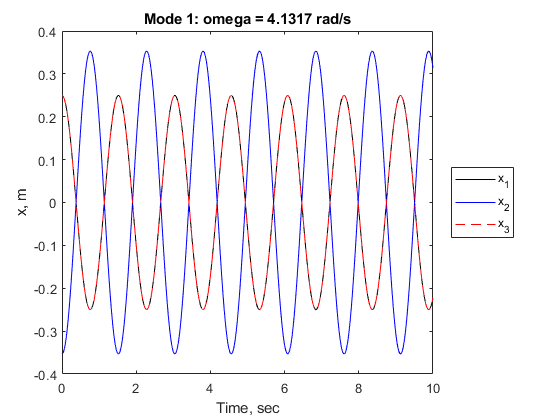

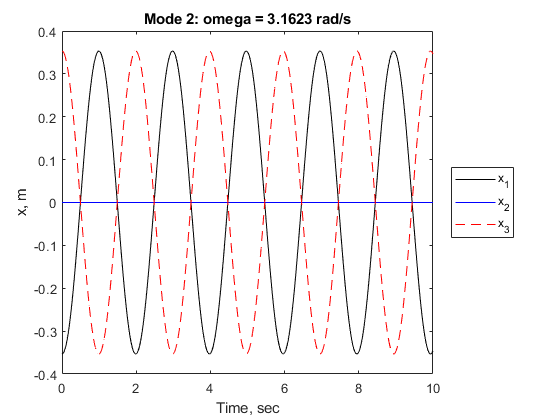

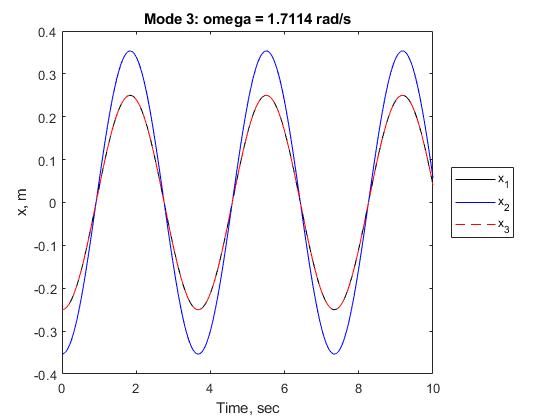

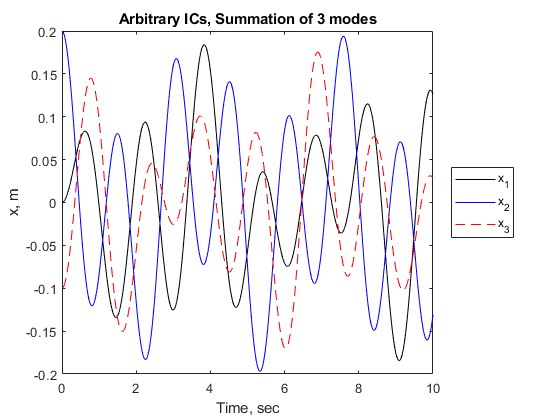

IC{1} = c(:,1)/2; % eigenvector (mode shape) #1
IC{2} = c(:,2)/2; % eigenvector (mode shape) #2
IC{3} = c(:,3)/2; % eigenvector (mode shape) #3
IC{4} = [0;0.2;-0.1]; % general IC
T = linspace(0,10,301);
for i = 1:4
    x{i} = 0;
    CosCoef{i} = c^-1*IC{i};
    for j = 1:3
        x{i} = x{i}+c(:,j).*CosCoef{i}(j)*cos(omega(j)*T);
    end
    figure(i)
    plot(T,x{i}(1,:),'-k',T,x{i}(2,:),'-b',T,x{i}(3,:),'--r')
    xlabel('Time, sec')
    ylabel('x, m')
    if i<4
        titletext = ['Mode ', num2str(i) ': omega = ' num2str(omega(i)) ' rad/s'];
        title(titletext)
    else
        title('Arbitrary ICs, Summation of 3 modes')
    end
    legend('x_1','x_2','x_3','Location','eastoutside')
end

#### Animation of motion

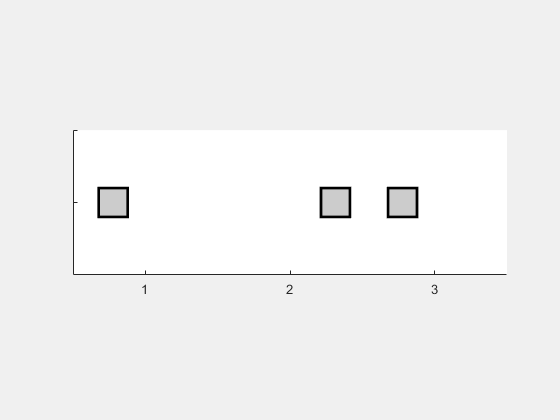

ican = 3; % select IC set to be animated
figure("Visible","on")
xcorners = [.1,-.1,-.1,.1];
ycorners = [.1,.1,-.1,-.1];
h(1) = patch(1+xcorners+x{ican}(1,1),ycorners,...
    'black','EdgeColor','black','FaceColor',[.8,.8,.8],'LineWidth',2);
h(2) = patch(2+xcorners+x{ican}(2,1),ycorners,...
    'black','EdgeColor','black','FaceColor',[.8,.8,.8],'LineWidth',2);
h(3) = patch(3+xcorners+x{ican}(3,1),ycorners,...
    'black','EdgeColor','black','FaceColor',[.8,.8,.8],'LineWidth',2);
axis equal
xlim([0.5,3.5])
ylim([-.5,.5])
set(gca,'XTick',0:1:4,'XTickLabel',[{""},{"1"},{"2"},{"3"},{""}])
set(gca,'YTick',-.5:.5:.5,'YTickLabel',[{""},{""},{""}])
 for n = 2:length(T)
     set(h(1),'XData',[1+xcorners+x{ican}(1,n)]);
     set(h(2),'XData',[2+xcorners+x{ican}(2,n)]);
     set(h(3),'XData',[3+xcorners+x{ican}(3,n)]);
     drawnow
     pause(1/50);
 end